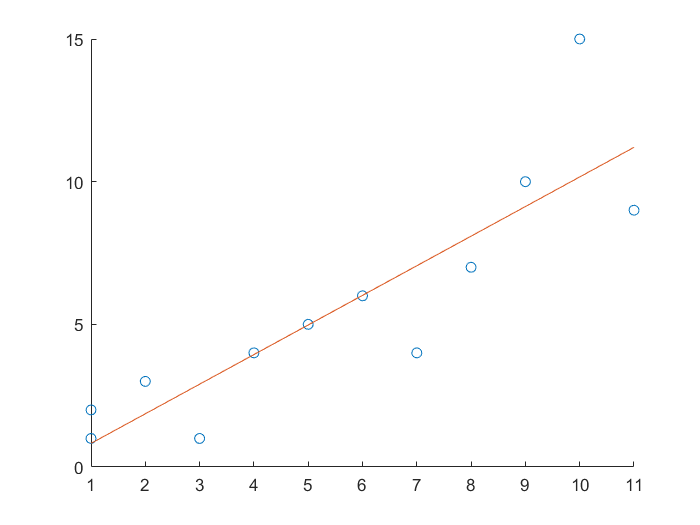

clear
clc

x_points = [1, 1, 2, 3, 4, 5, 6, 7, 8, 9, 10, 11];
y_points = [1, 2, 3, 1, 4, 5, 6, 4, 7, 10, 15, 9];
n = 1;

% x_points = -10:0.5:10;
% y_points = x_points+2*rand(1,length(x_points));
% n = 1;

% x_points = -5:0.1:5;
% y_points = x_points.^2+5*rand(1,length(x_points));
% n = 2;

% x_points=importdata("ex2x.dat")';
% y_points=importdata("ex2y.dat")';
% n = 1;

k_max = 100;
toll = 1e-6;

[p,res,iter,pvec,resvec] = poly_reg(x_points,y_points,n,k_max,toll);

x = min(x_points):0.1:max(x_points);
y = polyval(p,x);

scatter(x_points, y_points)
hold on
plot(x,y)
hold off

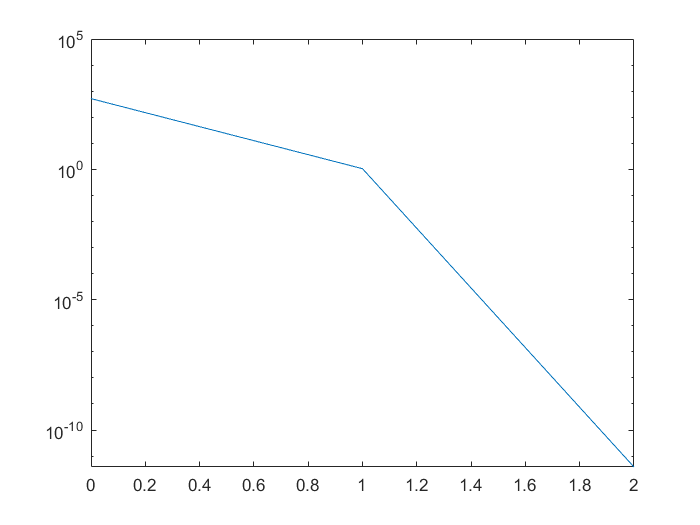


iter = 0:iter;
semilogy(iter,resvec)

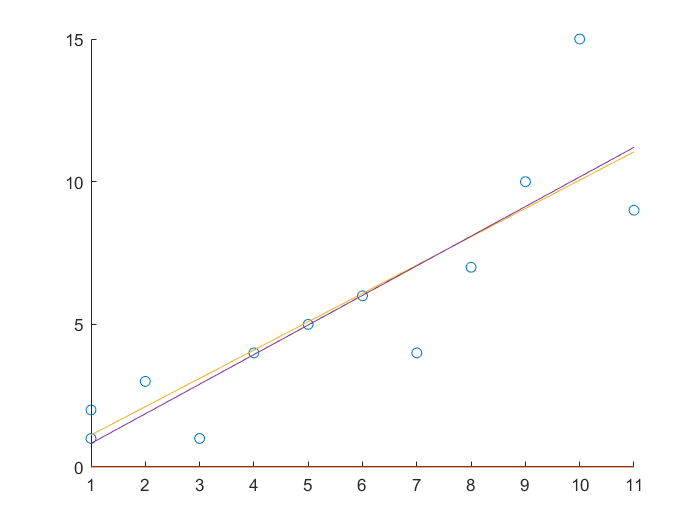

scatter(x_points, y_points)
hold on

x = min(x_points):0.1:max(x_points);

for k=1:size(pvec,2)
    y = polyval(pvec(:,k),x);
    plot(x,y)
end
hold off

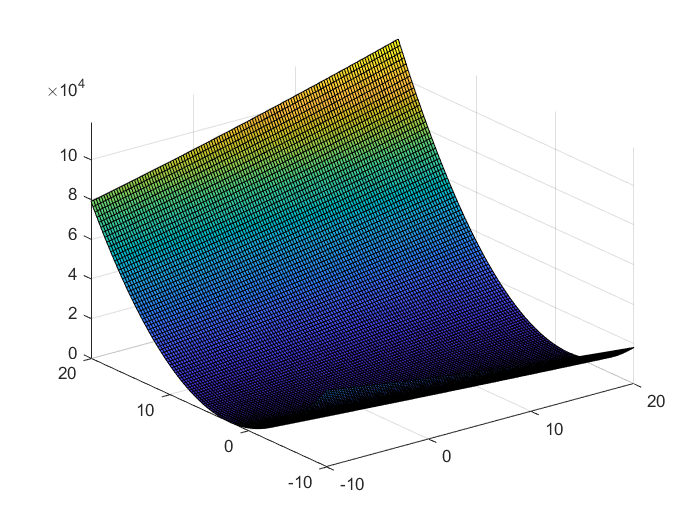

m = size(x_points,2);
n = n+1;
    
A = zeros(m,n);
for k=1:m
    for j=1:n
        A(k,j) = x_points(k)^(j-1);
    end
end
    
B = A'*A;
d = A'*y_points';

x1 = -10:0.25:20;
x2 = -10:0.25:20;
[X1,X2] = meshgrid(x1,x2);

E = (1/2)*(B(1,1)*X1.^2+(B(1,2)+B(2,1))*X1.*X2+B(2,2)*X2.^2)-(d(1)*X1+d(2)*X2);
% E = 1/2*X'*B*X-X'*d;
surf(X1,X2,E);

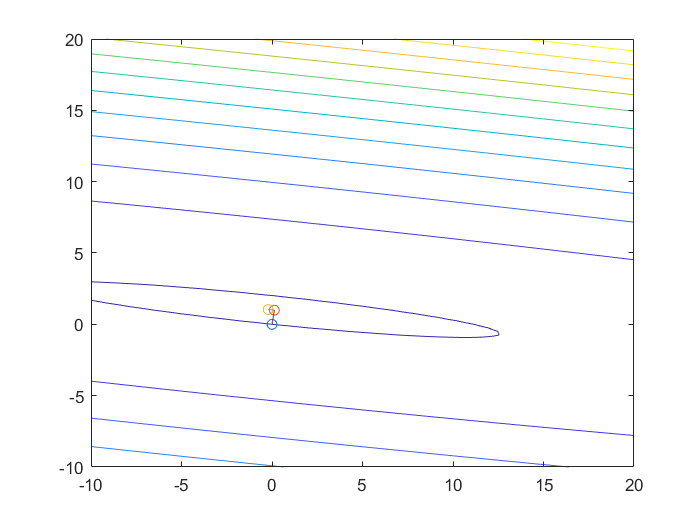


contour(X1,X2,E);
hold on

points = flip(pvec,1);
for k=1:size(points,2)
    scatter(points(1,k),points(2,k)); 
end

for k=1:size(points,2)-1
    P1 = points(:,k);
    P2 = points(:,k+1);
    D = P2-P1;
    quiver(P1(1),P1(2),D(1),D(2),0)
end
hold off

% function M = mat_pre(A)
%     % function per la costruzione di una matrice precondizionante M a banda
%     n=size(A,1); %numero di righe della matrice A 
%     %estrazioni diagonali della matrice A
%     diag_1 = diag (A);
%     diag_2 = diag(A,1);
%     diag_3 = diag(A,-1);
%     %inizializzazione matrice M
%     M = diag (diag_1);
%     %ciclo for per la costruzione della matrice M
%     for i=1:n-1
%         M(i,i+1)=diag_2(i);
%         M(i+1,i)=diag_3(i);
%     end
% end